# Edge detection

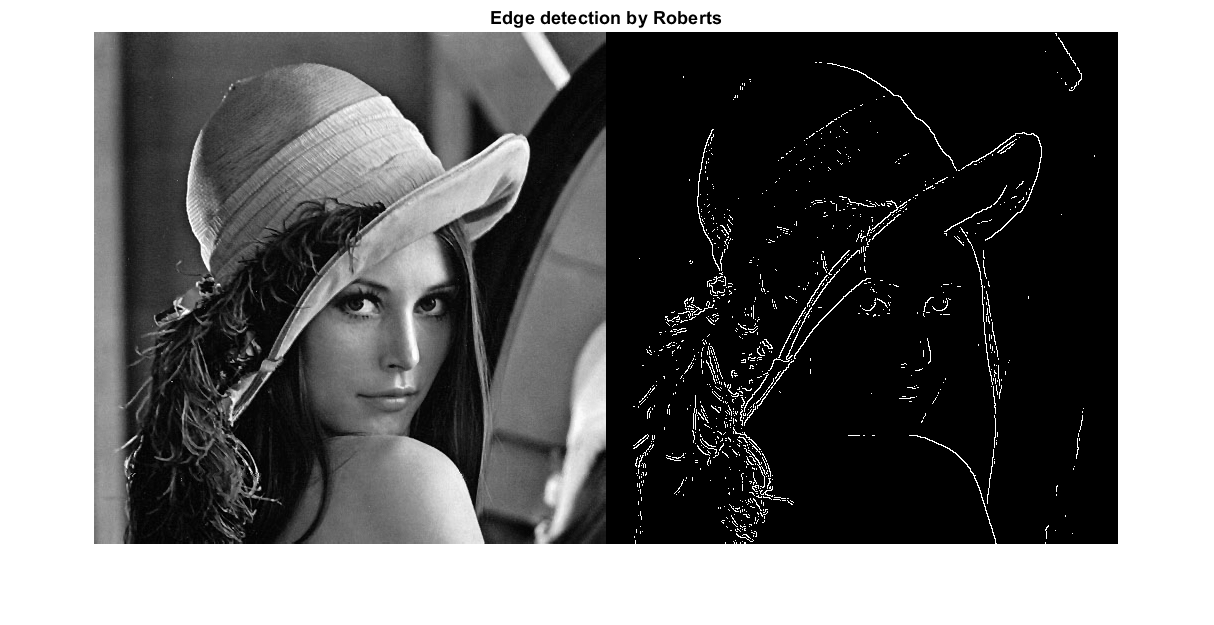

% read image
img = imread('image.png');
img = rgb2gray(img);

% apply the edge detection filter to the image
imgEdgeRoberts = edge(img, 'roberts');

imgEdgePrewitt = edge(img, 'prewitt');

imgEdgeSobel = edge(img, 'sobel');

% show images
imshowpair(img, imgEdgeRoberts, 'montage');
title('Edge detection by Roberts')

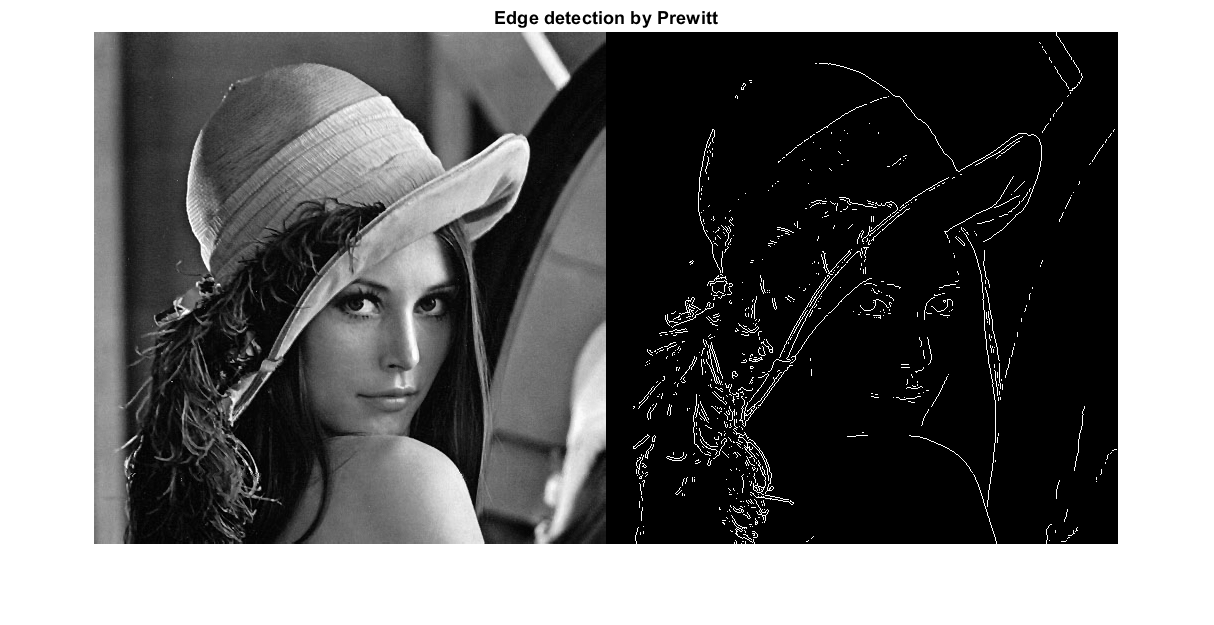


imshowpair(img, imgEdgePrewitt, 'montage');
title('Edge detection by Prewitt')

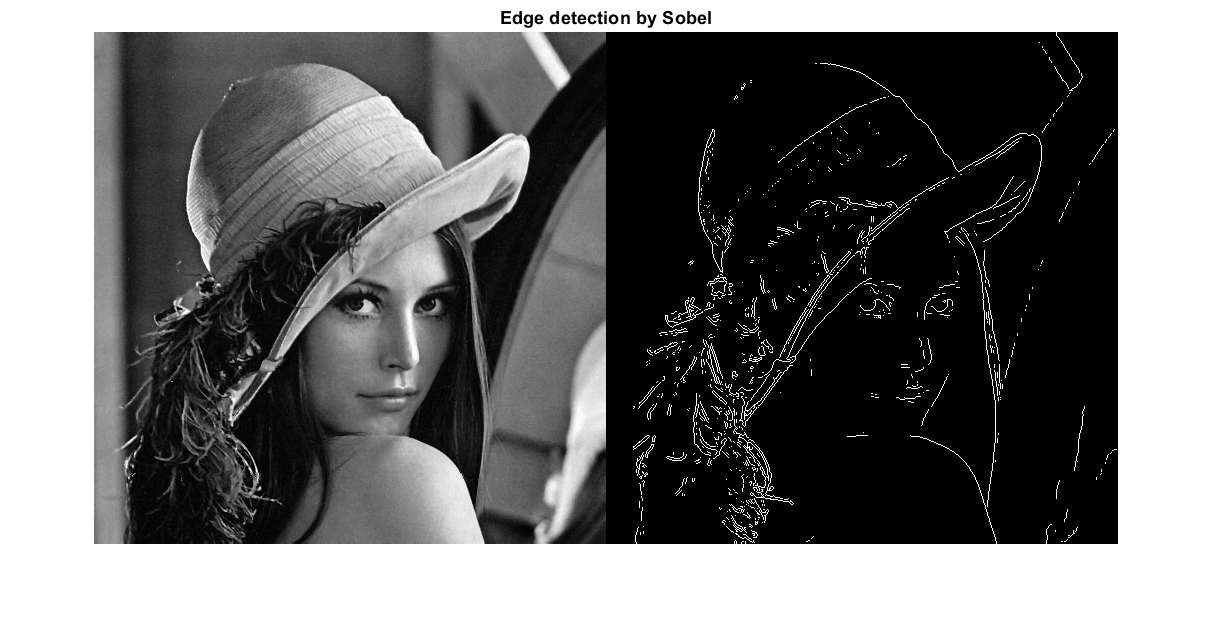


imshowpair(img, imgEdgeSobel, 'montage');
title('Edge detection by Sobel')

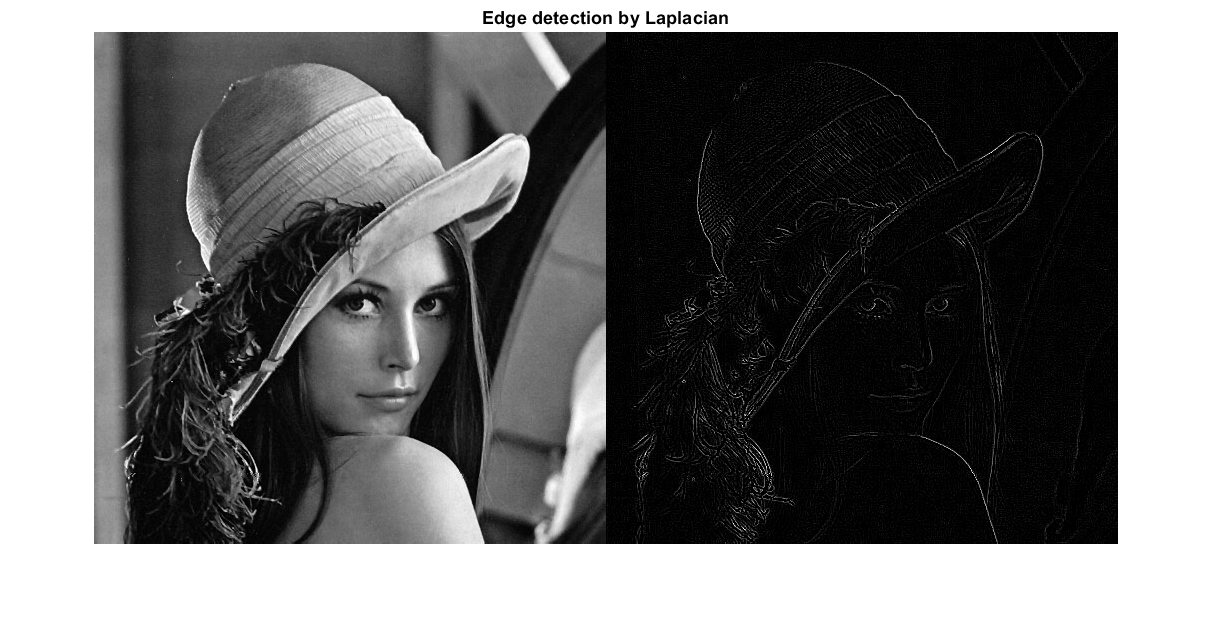

% laplacian filter to an image
img = imread('image.png');
img = rgb2gray(img);

% use fspecial to create laplacian filter
filter = fspecial('laplacian');

imgEdgeLaplace = imfilter(img, filter, 'symmetric');

imshowpair(img, imgEdgeLaplace, 'montage');
title('Edge detection by Laplacian')